% Generar datos aleatorios cerca de una recta en la dirección (1, 1, 1) en 3D
rng(0); % Fijar la semilla para reproducibilidad
n = 30; % Número de datos
t = linspace(-10, 10, n)'; % Valores de t distribuidos uniformemente
x = t + randn(n, 1) * 0.5; % Valores de x con ruido
y = t + randn(n, 1) * 8; % Valores de y con ruido
z = t + randn(n, 1) * 3; % Valores de z con ruido
X = [x, y, z];


% Visualizar los datos en un gráfico 3D
figure;
scatter3(X(:,1), X(:,2), X(:,3), 'filled');
xlabel('X');
ylabel('Y');
zlabel('Z');
title('Datos 3D distribuidos cerca de una recta en la dirección (1, 1, 1)');
grid on;

% Estandarización de los Datos 
X_E = ( X - mean(X))./ std(X); % Centrar los datos
 

% Calcular la matriz de covarianza
cov_matrix =  X_E'*X_E/(n-1); %%%%%%%%%%%%%%%%%%   ENTRADA REQUEDIDA

% Realizar la descomposición en valores singulares (SVD)
[U, S, V] = svd( cov_matrix);  %   ENTRADA REQUEDIDA ELIMINAR COV_MATRIX

% Mostrar los valores singulares
disp('Valores Singulares:');

Valores Singulares:


disp(diag(S));

    2.3873
    0.5631
    0.0496




% Mostrar los vectores singulares (componentes principales)
disp('Vectores Singulares (Componentes Principales):');

Vectores Singulares (Componentes Principales):


disp(V);

   -0.6337    0.1494   -0.7590
   -0.5090   -0.8194    0.2637
   -0.5825    0.5534    0.5953



C1 = V(:,1)    %%%%%%%%%%%%%%%%%%   ENTRADA REQUEDIDA

C1 =    -0.6337
   -0.5090
   -0.5825


C2 = V(:,2)    %%%%%%%%%%%%%%%%%%   ENTRADA REQUEDIDA

C2 =     0.1494
   -0.8194
    0.5534


C3 = V(:,3)    %%%%%%%%%%%%%%%%%%   ENTRADA REQUEDIDA

C3 =    -0.7590
    0.2637
    0.5953


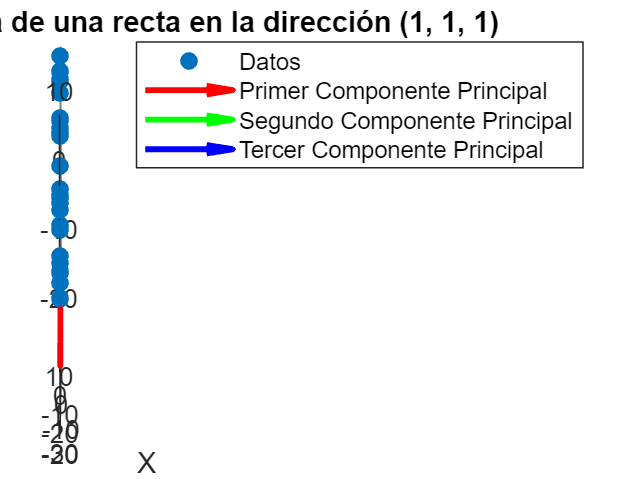


% Visualizar los vectores principales superpuestos en los datos
hold on;
C1= C1 ;  
C2= C2*S(2,2)/S(1);
C3= C3*S(3,3)/S(1);
mean_data = mean(X');
quiver3(mean_data(1), mean_data(2), mean_data(3), C1(1), C1(2), C1(3), 10, 'r', 'LineWidth', 2);
quiver3(mean_data(1), mean_data(2), mean_data(3), C2(1), C2(2), C2(3), 10, 'g', 'LineWidth', 2);
quiver3(mean_data(1), mean_data(2), mean_data(3), C3(1), C3(2), C3(3), 10, 'b', 'LineWidth', 2);
legend('Datos', 'Primer Componente Principal', 'Segundo Componente Principal', 'Tercer Componente Principal');
hold off;





% Parámetros del cono
r = 5;
h = 12;

% Calcule el volumen del cono utilizando las variables r y h.
vol = pi*r^2*h /3

vol = 314.1593